# Kane Mele (H(k)) lattice model

just copy [https://yxli8023.github.io/2020/07/05/Kane-Mele-derive.html](https://yxli8023.github.io/2020/07/05/Kane-Mele-derive.html)

他这个推错了

应该按照这个结果

[https://arxiv.org/pdf/1408.4507.pdf](https://arxiv.org/pdf/1408.4507.pdf)

we have $$\mathcal{H}=t\left(\left(-2 \cos \left(\frac{k_{x}}{2}\right)-\cos \left(\frac{\sqrt{3} k_{y}}{2}\right)\right) \sigma_{x} s_{0}-\sin \left(\frac{k_{x}}{2}\right) \sigma_{y} s_{0}\right)+4 \lambda_{s o} \sin \left(\frac{k_{x}}{2}\right)\left(\cos \left(\frac{k_{x}}{2}\right)-\cos \left(\frac{\sqrt{3} k_{y}}{2}\right)\right) \sigma_{z} s_{z}$$

Τhen we take a try

%% useful_tools
sigma_0 = pauli_matric(0); sigma_x = pauli_matric(1); sigma_y = pauli_matric(2); sigma_z = pauli_matric(3);
s_0   = pauli_matric(0); s_x   = pauli_matric(1); s_y   = pauli_matric(2); s_z   = pauli_matric(3);
%
syms t k_x k_y k_z lambda_SO real
%
Kane_Mele = HK(4);
Kane_Mele = Kane_Mele  ...
    + Trig( t*(-2*cos(3^(1/2)*k_x/2)-cos(3*k_y/2))       ,    sigma_x*s_0)...
    + Trig( t*(-          sin(3*k_y/2))          ,    sigma_y*s_0)...
    + Trig( 4*lambda_SO*(sin(3^(1/2)*k_x/2)*(cos(3^(1/2)*k_x/2)-cos(3*k_y/2)))  ,    sigma_z*s_z)...
    ;

Kane_Mele= Kane_Mele < 'POSCAR';
Kane_Mele =Kane_Mele < 'KPOINTS';
%% 

####  para

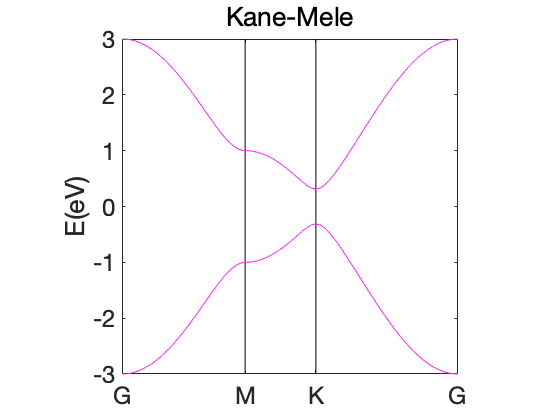

%
t  =   1;
lambda_SO =0.06;

Kane_Mele_n = Kane_Mele.Subsall();
%
EIGENCAR = Kane_Mele_n.EIGENCAR_gen();
bandplot(EIGENCAR,[-3,3]);